# **Simulation Assignment**

## **Name- D.S.B.C.L.JAYAWEERA**

## **Index - 180288L**

## **Question 1**

L = 1000;  %the length
D = zeros(1,L); %sequence of 1000 zeros
p = randperm(L,L/2); %500 random numbers between 1 and 1000 
                                                            
D(p) = ones(1,L/2); %replacing the zeros in D with ones locations are specified in p
A=1;

%generating a sequence of pulses

S = zeros(1,L); %1000 zeros transmitting initialy
for i = 1:L 
    if D(i) == 0 %-A if D = 0
        S(i) = -1*A;
    else
        S(i) = A; %A if D = 1
    end
end

## **Question 2 , Question 3**

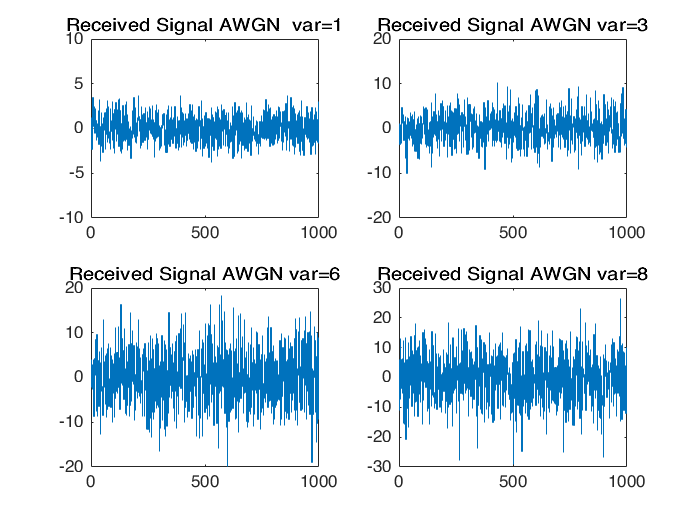

%%%Generate an AWGN sequences  (variance =1, mean=0)

mean = 0;

%each signal variances
sigma = 1;
sigma_2 = 3;
sigma_3 = 6;
sigma_4 = 8;

%each signal calculated noises
Noise = mean + sigma*randn(1,L);
Noise_2 = mean + sigma_2*randn(1,L);
Noise_3 = mean + sigma_3*randn(1,L);
Noise_4= mean + sigma_4*randn(1,L);

%each received signals
R_1 = S + Noise;
R_2 = S + Noise_2;
R_3 = S + Noise_3;
R_4 = S + Noise_4;

%figure1 = figure("position", [100,100,3000,2800]);
subplot(2,2,1);
stairs([1:L],R_1);
title("Received Signal AWGN  var=1");
ylim([-10 10]);

subplot(2,2,2);
stairs([1:L],R_2);
title("Received Signal AWGN var=3");
ylim([-20 20]);

subplot(2,2,3);
stairs([1:L],R_3);
title("Received Signal AWGN var=6");
ylim([-20 20]);

subplot(2,2,4);
stairs([1:L],R_4);
title("Received Signal AWGN var=8");
ylim([-30 30]);

## Observation - when we increase our variance of the signal then received signal amplitude also incease. variance and the amplitude of the received signal is propotional.

## **Question 4**

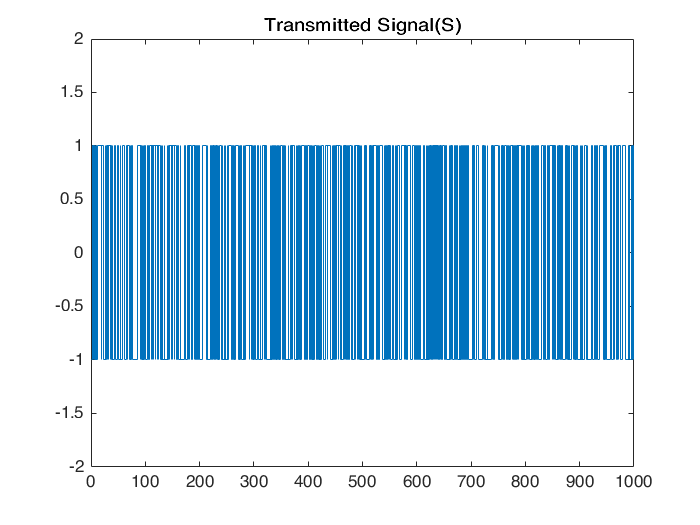

% R_1 previous signal mean =0 and sigma = 1,

%generating Y sequence%%%%
close
tau = 0;    %%threshold
Y = zeros(1,L);  %%% sequence of 1000 of zeros
for i = 1:L
    if R_1(i) > tau
    Y(i) = A;
    else
    Y(i) = -1*A;
    end
end

%%compare the transmit and decode signals
A=1;
figure;
stairs([1:L],S);
title("Transmitted Signal(S)");
xlim([0 L]); 
ylim([-1*(A+1) A+1]);

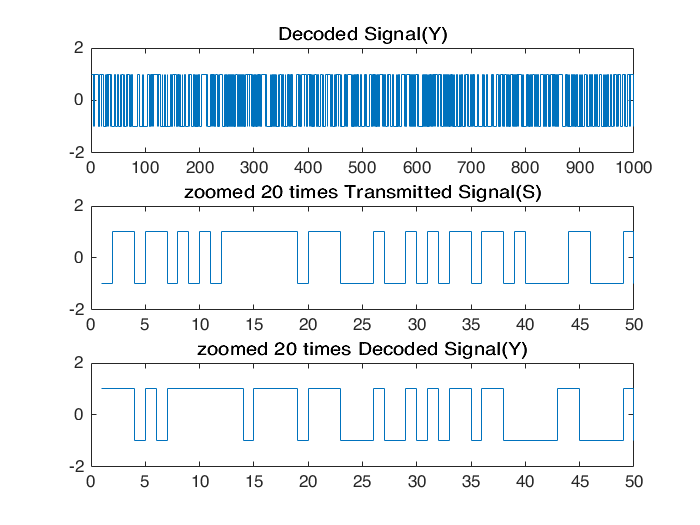


subplot(3,1,1);
stairs([1:L],Y);
title("Decoded Signal(Y)");
xlim([0 L]); 
ylim([-1*(A+1) A+1]);

%%compare with the same signals with zoomed 20 times
subplot(3,1,2);
stairs([1:L],S);
title("zoomed 20 times Transmitted Signal(S)");
xlim([0 L/20]); 
ylim([-1*(A+1) A+1]);

subplot(3,1,3);
stairs([1:L],Y);
title("zoomed 20 times Decoded Signal(Y)");
xlim([0 L/20]); 
ylim([-1*(A+1) A+1]);

## **Observation - we can identify easily transmit and decode signals difference using zoomed signal. Both of signal similar but, some of points are slightly difference so,we can say most of the bits identified correctly in decoding. But, there are some of the bits errors.**

## **Question 5**

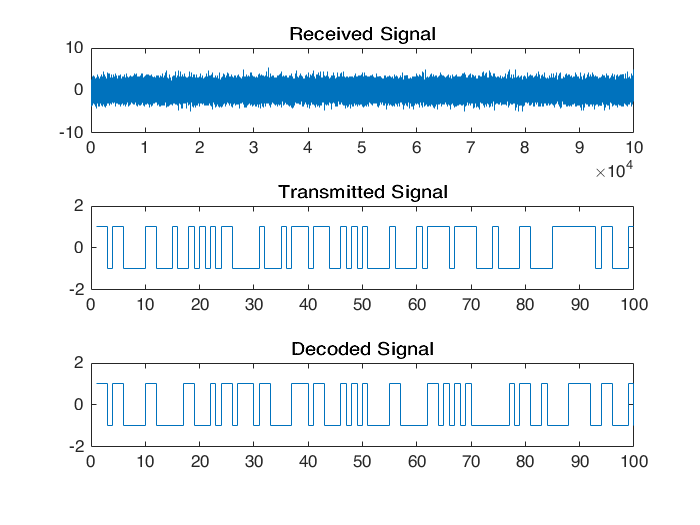

%generating binary sequence 100000 length 
L = 100000;

D = zeros(1,L); %sequence of 100000 zeros
p = randperm(L,L/2); %500 random numbers between 1 and 100000 
                                                            
D(p) = ones(1,L/2); %replacing the zeros in D with ones locations are specified in p
A=1;

%generating a sequence of pulses

S = zeros(1,L); %100000 zeros transmitting initialy
for i = 1:L 
    if D(i) == 0 %-A if D = 0
        S(i) = -1*A;
    else
        S(i) = A; %A if D = 1
    end
end



subplot(3,1,1);
mean = 0;
sigma = 1;
Noise = mean + sigma*randn(1,L);
R_1 = S + Noise;
stairs([1:L],R_1);
title("Received Signal");

tau = 0;
Y = zeros(1,L);
for j = 1:L
if R_1(j) > tau
 Y(j) = A;
else
 Y(j) = -1*A;
end
end

subplot(3,1,2);
stairs([1:L],S);
title("Transmitted Signal");
xlim([0 L/1000]); 
ylim([-1*(A+1) A+1]);

subplot(3,1,3);
stairs([1:L],Y);
title("Decoded Signal");
xlim([0 L/1000]); 
ylim([-1*(A+1) A+1]);

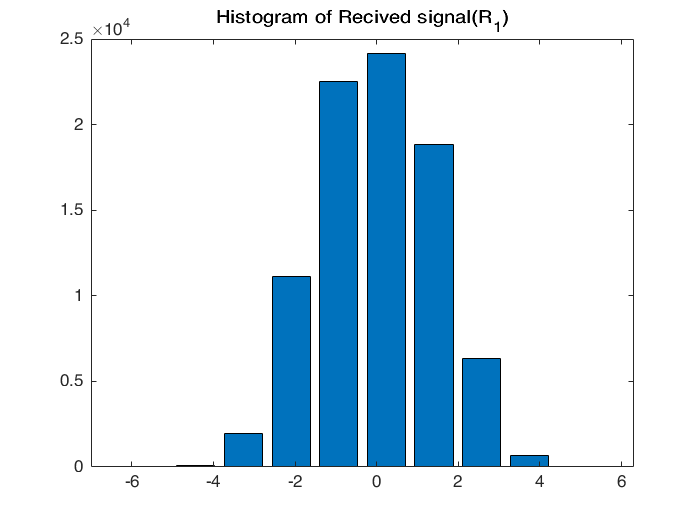

%generating the bins sequence
bin_count = 10; % bins count
R_max = max(R_1);
R_min = min(R_1);
W = (R_max-R_min)/(bin_count-1); %width of this
bins = [R_min-W/2:W:R_max];

%bin how much data count
D_count = zeros(1,bin_count);
for i = 1:L
    for a = 1:bin_count
        if (R_1(i) >= bins(a)-W/2) && (R_1(i) < bins(a)+W/2)
            D_count(a) = D_count(a) + 1;
        end
    end
end
new = D_count/W;
%histogram
figure;
bar(bins,new);
title("Histogram of Recived signal(R_1)");

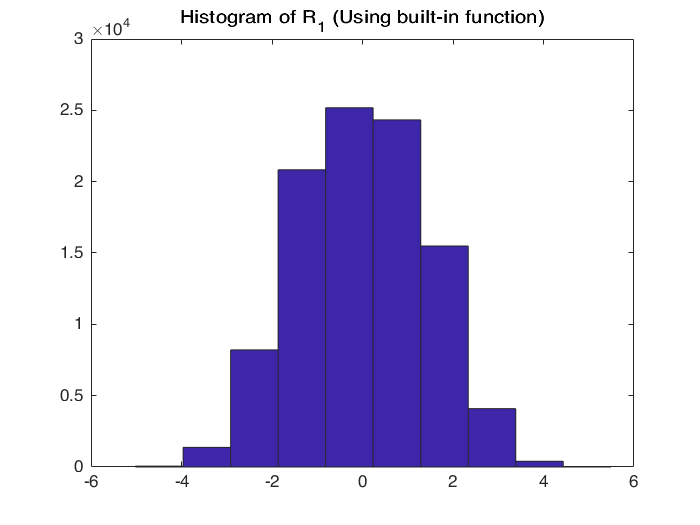


figure;
hist(R_1,bin_count); %Matlab built in function
title("Histogram of R_1 (Using built-in function)");

## **Observation - **There is a small difference between them with respect to frequency.

## **Question 5 part a**

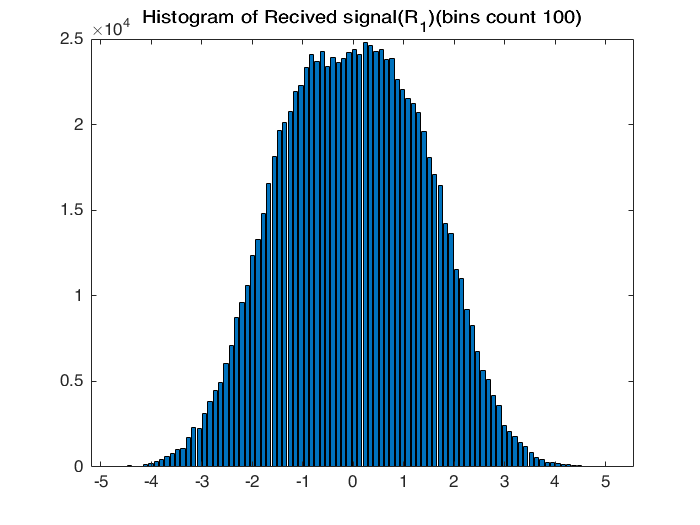

%generating the bins sequence
bin_count = 100; % bins count 100
R_max = max(R_1);
R_min = min(R_1);
W = (R_max-R_min)/(bin_count-1); %width of this
bins = [R_min-W/2:W:R_max];

%bin how much data count
D_count = zeros(1,bin_count);
for i = 1:L
    for a = 1:bin_count
        if (R_1(i) >= bins(a)-W/2) && (R_1(i) < bins(a)+W/2)
            D_count(a) = D_count(a) + 1;
        end
    end
end
new = D_count/W;
%histogram
figure;
bar(bins,new);
title("Histogram of Recived signal(R_1)(bins count 100)");

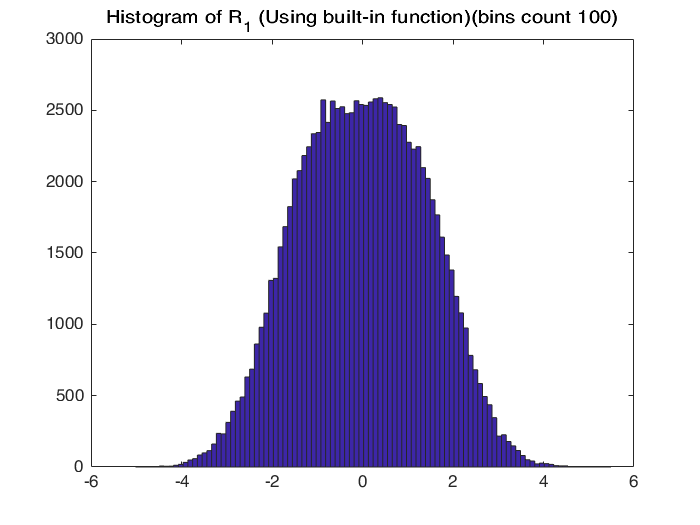


figure;
hist(R_1,bin_count); %Matlab built in function
title("Histogram of R_1 (Using built-in function)(bins count 100)");

## **Observation - **Increase bin count then reduce the difference between two shapes.we can see that Y axes are different.Because In built function gives  normalized version of histogram

## **Question 5 part b**

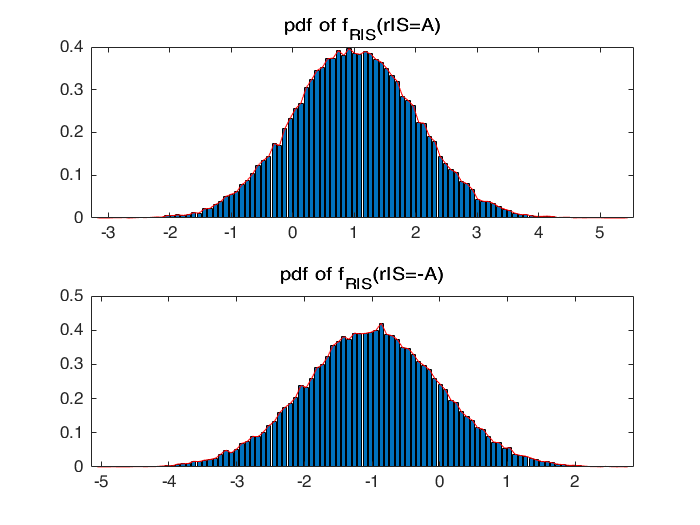

%plotting f_R|S(r|S=A)
RS_1 = []; %create a list R_1 values S = A
index = 1;
for i = 1:L
    if S(i) == A
        RS_1(index) = R_1(i);
        index = index + 1;
    end
end

bin = 100;
R_maxSA = max(RS_1);
R_minSA = min(RS_1);
W_1 = (R_maxSA-R_minSA)/(bin-1); %width of SA
bins_SA = [R_minSA-W_1/2:W_1:R_maxSA]; 
[y_val1,x_val1] = hist(RS_1,bins_SA); %histogram
y_val1 = y_val1/((index-1)*W_1);


%plotting the pdf of f_R|S(r|S=-A)
RS_0 = [];  %create a list contain R values S = -A
index = 1;
for i = 1:L
    if S(i) == -1*A
        RS_0(index) = R_1(i);
        index = index + 1;
    end
end
bin = 100;
R_maxS_A = max(RS_0);
R_minS_A = min(RS_0);
widthS_A = (R_maxS_A-R_minS_A)/(bin-1); 
binsS_A = [R_minS_A-widthS_A/2:widthS_A:R_maxS_A]; 
[y_val2,x_val2] = hist(RS_0,binsS_A); %histogram
y_val2 = y_val2/((index-1)*widthS_A);


%%plotting the pdf
%figure4 = figure("position", [50,50,3000,2800]);
subplot(2,1,1);
bar(x_val1,y_val1);
hold on;
plot(x_val1,y_val1,'r'); %pdf
title("pdf of f_{R|S}(r|S=A)");


%plotting the pdf
subplot(2,1,2);
bar(x_val2,y_val2);
hold on;
plot(x_val2,y_val2,'r'); % pdf
title("pdf of f_{R|S}(r|S=-A)");

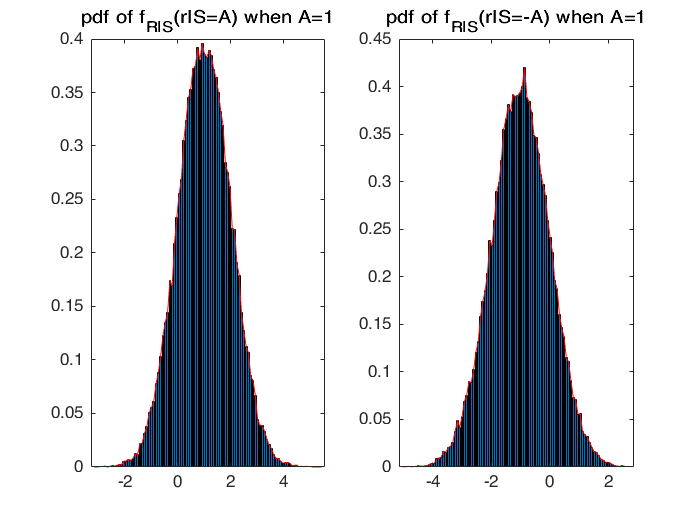

A=1;
%generate a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
R = S + Noise;
RS_1 = []; %list containing R values S = A
index = 1;
for i = 1:L
    if S(i) == A
        RS_1(index) = R(i);
        index = index + 1;
    end
end
bin = 100;
RS_max1 = max(RS_1);
RS_min1 = min(RS_1);
W_3 = (RS_max1-RS_min1)/(bin-1); % bin width
bins_1 = [RS_min1-W_3/2:W_3:RS_max1]; %bins list
[yval1,xval1] = hist(RS_1,bins_1); %plot the histogram
yval1 = yval1/((index-1)*W_3);
%plotting the pdf of f_R|S(r|S=-A)
R_0 = []; %list containing R values S = -A
index = 1;
for i = 1:L
    if S(i) == -1*A
        R_0(index) = R(i);
        index = index + 1;
    end
end

bin = 100;
RS_max2 = max(R_0);
RS_min2 = min(R_0);
W_3 = (RS_max2-RS_min2)/(bin-1); %bin width
bins_2 = [RS_min2-W_3/2:W_3:RS_max2]; %bins list
[yval2,xval2] = hist(R_0,bins_2); %plot the histogram
yval2 = yval2/((index-1)*W_3);


subplot(1,2,1);
bar(xval1,yval1);
hold on;
plot(xval1,yval1,'r'); %plotting the pdf
title("pdf of f_{R|S}(r|S=A) when A=1");
subplot(1,2,2);
bar(xval2,yval2);
hold on;
plot(xval2,yval2,'r'); %plotting the pdf
title("pdf of f_{R|S}(r|S=-A) when A=1");

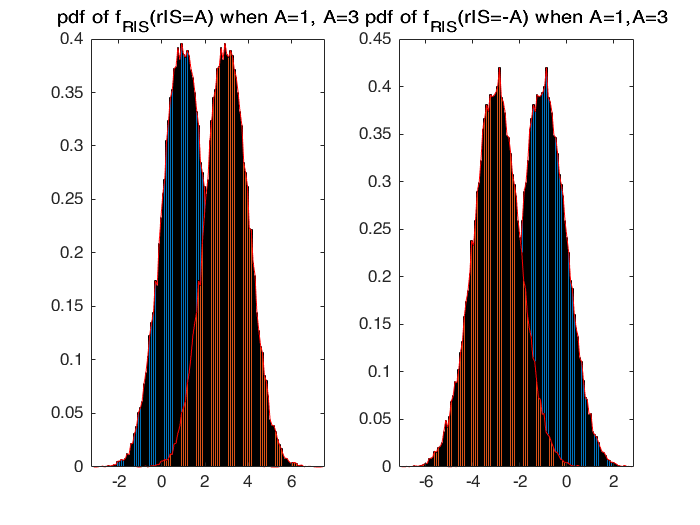


A=3;
%generate a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
R = S + Noise;
RS_1 = []; %list containing R values S = A
index = 1;
for i = 1:L
    if S(i) == A
        RS_1(index) = R(i);
        index = index + 1;
    end
end
bin = 100;
RS_max1 = max(RS_1);
RS_min1 = min(RS_1);
W_3 = (RS_max1-RS_min1)/(bin-1); % bin width
bins_1 = [RS_min1-W_3/2:W_3:RS_max1]; %bins list
[yval1,xval1] = hist(RS_1,bins_1); %plot the histogram
yval1 = yval1/((index-1)*W_3);
%plotting the pdf of f_R|S(r|S=-A)
R_0 = []; %list containing R values S = -A
index = 1;
for i = 1:L
    if S(i) == -1*A
        R_0(index) = R(i);
        index = index + 1;
    end
end

bin = 100;
RS_max2 = max(R_0);
RS_min2 = min(R_0);
W_3 = (RS_max2-RS_min2)/(bin-1); %bin width
bins_2 = [RS_min2-W_3/2:W_3:RS_max2]; %bins list
[yval2,xval2] = hist(R_0,bins_2); %plot the histogram
yval2 = yval2/((index-1)*W_3);


subplot(1,2,1);
bar(xval1,yval1);
hold on;
plot(xval1,yval1,'r'); %plotting the pdf
title("pdf of f_{R|S}(r|S=A) when A=1, A=3");
subplot(1,2,2);
bar(xval2,yval2);
hold on;
plot(xval2,yval2,'r'); %plotting the pdf
title("pdf of f_{R|S}(r|S=-A) when A=1,A=3");

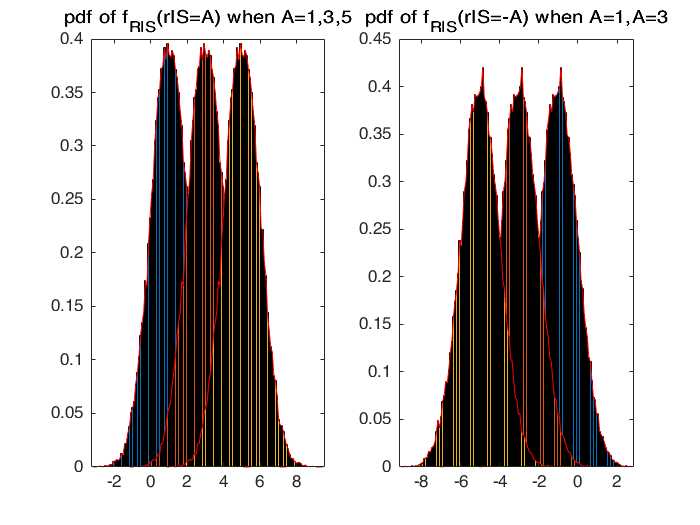

A=5;
%generate a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
R = S + Noise;
RS_1 = []; %list containing R values S = A
index = 1;
for i = 1:L
    if S(i) == A
        RS_1(index) = R(i);
        index = index + 1;
    end
end
bin = 100;
RS_max1 = max(RS_1);
RS_min1 = min(RS_1);
W_3 = (RS_max1-RS_min1)/(bin-1); % bin width
bins_1 = [RS_min1-W_3/2:W_3:RS_max1]; %bins list
[yval1,xval1] = hist(RS_1,bins_1); %plot the histogram
yval1 = yval1/((index-1)*W_3);

%plotting the pdf of f_R|S(r|S=-A)
R_0 = []; %list containing R values S = -A
index = 1;
for i = 1:L
    if S(i) == -1*A
        R_0(index) = R(i);
        index = index + 1;
    end
end

bin = 100;
RS_max2 = max(R_0);
RS_min2 = min(R_0);
W_3 = (RS_max2-RS_min2)/(bin-1); %bin width
bins_2 = [RS_min2-W_3/2:W_3:RS_max2]; %bins list
[yval2,xval2] = hist(R_0,bins_2); %plot the histogram
yval2 = yval2/((index-1)*W_3);

%figure5 = figure("position", [100,100,700,300]);
subplot(1,2,1);
bar(xval1,yval1);
hold on;
plot(xval1,yval1,'r'); %plotting the pdf
title("pdf of f_{R|S}(r|S=A) when A=1,3,5");
subplot(1,2,2);
bar(xval2,yval2);
hold on;
plot(xval2,yval2,'r'); %plotting the pdf

## **Observation- **When A is increasing each graph move away from zero.That means mean value move away from zero  when increasing A.

## **Question 5 part c**

A=1;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
if D(i) == 0 
 S(i) = -1*A;
else
 S(i) = A; 
end
end
R = S + Noise;

%calculating E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%calculating E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%calculating E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W_3);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=1");

For A=1


ER_SMA

ER_SMA = -5.0015

ER_SA

ER_SA = 5.0039

E_R

E_R = 0.0015

disp(" ");



A=3;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
if D(i) == 0 
 S(i) = -1*A;
else
 S(i) = A; 
end
end
R = S + Noise;

%calculating E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%calculating E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%calculating E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=3");

For A=3


ER_SMA

ER_SMA = -5.0015

ER_SA

ER_SA = 5.0039

E_R

E_R = 0.0034

disp(" ");


A=5;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
if D(i) == 0 
 S(i) = -1*A;
else
 S(i) = A; 
end
end
R = S + Noise;

%calculating E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%calculating E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%calculating E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=5");

For A=5


ER_SMA

ER_SMA = -5.0015

ER_SA

ER_SA = 5.0039

E_R

E_R = 0.0737

disp(" ");

## **Question 5 part d**

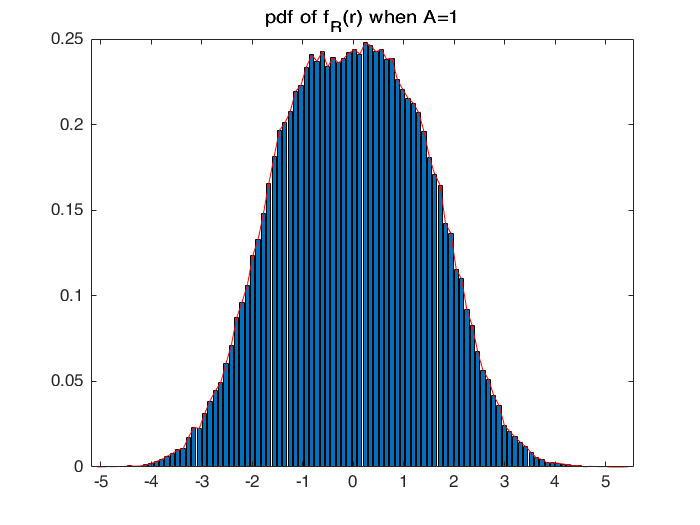


A=1;
%generate a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
R = S + Noise;

%calculating E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%calculating E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%calculating E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

%plot the pdf of f_R(r)
figure;
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A=1")

## **Question 6**

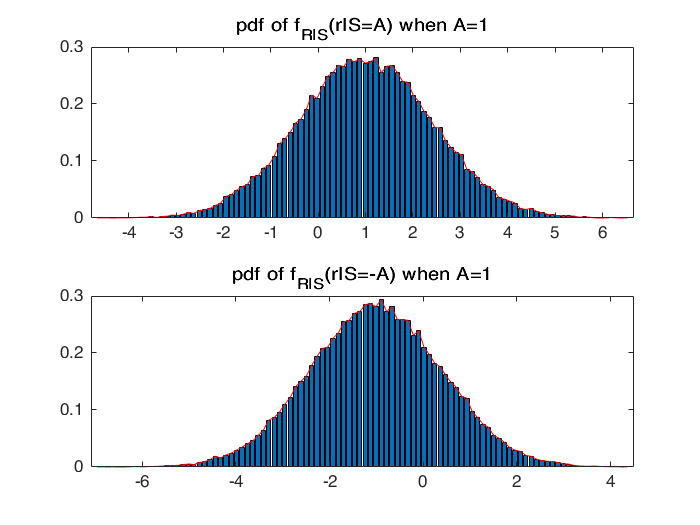


%generate recieved signal with intterference
mean = 0;
sigma = 1;
I = mean + sigma*randn(1,L);
R = S + Noise + I;


%plotting the pdf of f_R|S(r|S=A)
R_1 = []; 
index = 1;

for i = 1:L
if S(i) == A
 R_1(index) = R(i);
 index = index + 1;
end
end
bin = 100;
R_max1 = max(R_1);
R_min1 = min(R_1);
W_1 = (R_max1-R_min1)/(bin-1); %sbin width
bins_1 = [R_min1-W_1/2:W_1:R_max1]; 
[yval1,xval1] = hist(R_1,bins_1); 
yval1 = yval1/((index-1)*W_1);

%plotting the pdf of f_R|S(r|S=-A)
R_0 = []; % list containing R values when S = -A
index = 1;
for i = 1:L
if S(i) == -1*A
 R_0(index) = R(i);
 index = index + 1;
end
end
bin = 100;
R_max2 = max(R_0);
R_min2 = min(R_0);
widthS_A = (R_max2-R_min2)/(bin-1); 
bins_2 = [R_min2-widthS_A/2:widthS_A:R_max2]; 
[yval2,xval2] = hist(R_0,bins_2); 
yval2 = yval2/((index-1)*widthS_A);

subplot(2,1,1);
bar(xval1,yval1);
hold on;
plot(xval1,yval1,'r'); 
title("pdf of f_{R|S}(r|S=A) when A=1");

subplot(2,1,2);
bar(xval2,yval2);
hold on;
plot(xval2,yval2,'r'); 
title("pdf of f_{R|S}(r|S=-A) when A=1");

A=1;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=1")

For A=1


ER_SMA

ER_SMA = -1.0085

ER_SA

ER_SA = 0.9984

E_R

E_R = -0.0047

disp(" ")

A=3;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=3")

For A=3


ER_SMA

ER_SMA = -1.0085

ER_SA

ER_SA = 0.9984

E_R

E_R = 0.0048

disp(" ")

A=5;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end
disp("For A=5")

For A=5


ER_SMA

ER_SMA = -1.0085

ER_SA

ER_SA = 0.9984

E_R

E_R = 0.0737

disp(" ")

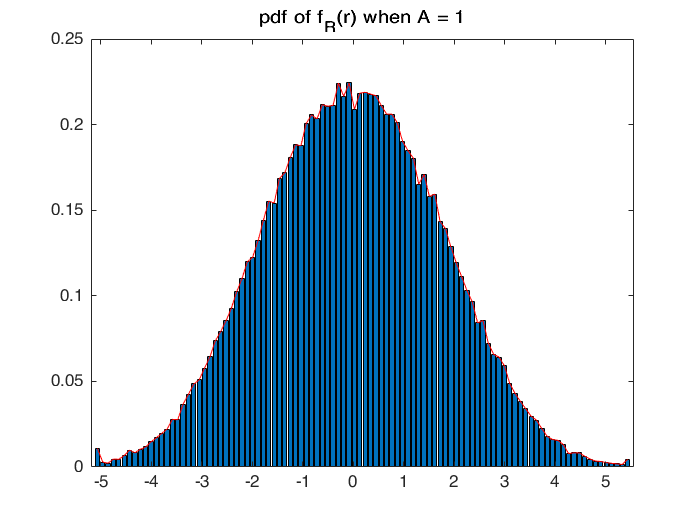


A=1;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

figure
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A = 1")

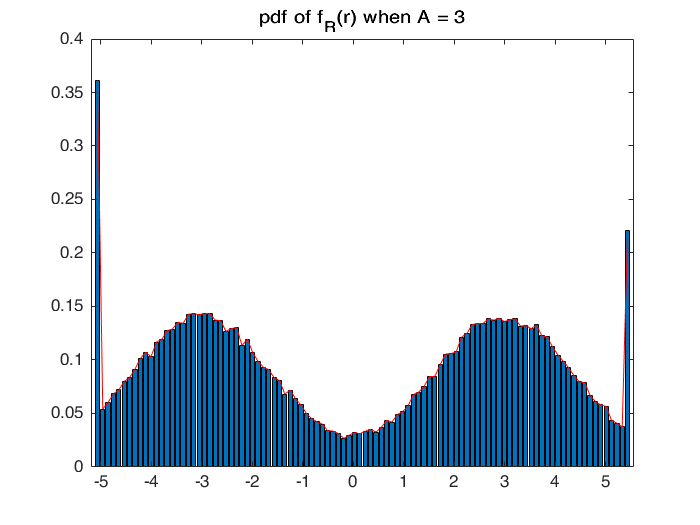


A=3;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

figure
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A = 3")

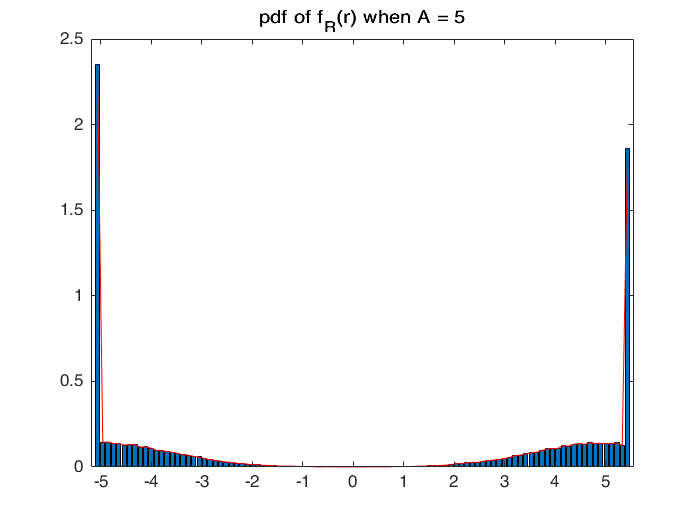


A=5;
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
mean = 0;
sigma = 1;
R = S + Noise + I;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

figure
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A = 5")

## **Question 7**

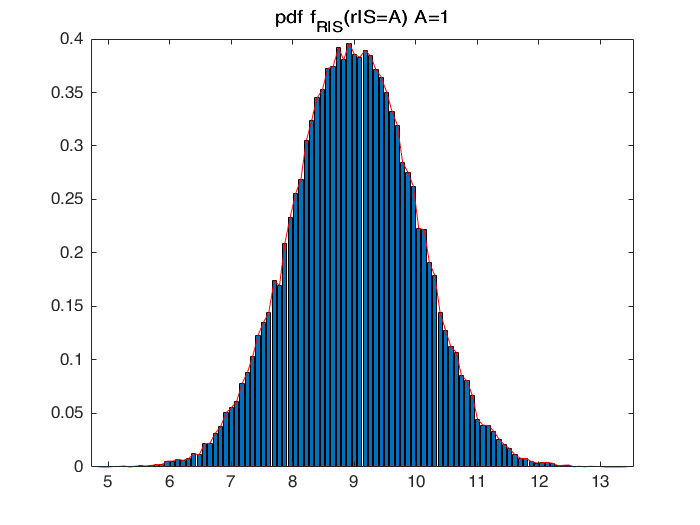

%generating the recieved signal with amplifying
alpha = 1.8;
R = alpha*S + Noise;

%plotting the pdf of f_R|S(r|S=A)
R_1 = []; 
index = 1;

for i = 1:L
    if S(i) == A
        R_1(index) = R(i);
        index = index + 1;
    end
end
bin = 100;
R_max1 = max(R_1);
R_min1 = min(R_1);
W_1 = (R_max1-R_min1)/(bin-1); %sbin width
bins_1 = [R_min1-W_1/2:W_1:R_max1]; 
[yval1,xval1] = hist(R_1,bins_1); 
yval1 = yval1/((index-1)*W_1);

%plotting the pdf of f_R|S(r|S=-A)
R_0 = []; % list containing R values when S = -A
index = 1;
for i = 1:L
    if S(i) == -1*A
        R_0(index) = R(i);
        index = index + 1;
    end
end
bin = 100;
R_max2 = max(R_0);
R_min2 = min(R_0);
widthS_A = (R_max2-R_min2)/(bin-1); 
bins_2 = [R_min2-widthS_A/2:widthS_A:R_max2]; 
[yval2,xval2] = hist(R_0,bins_2); 
yval2 = yval2/((index-1)*widthS_A);

figure
bar(xval1,yval1);
hold on;
plot(xval1,yval1,'r'); 
title("pdf f_{R|S}(r|S=A) A=1");

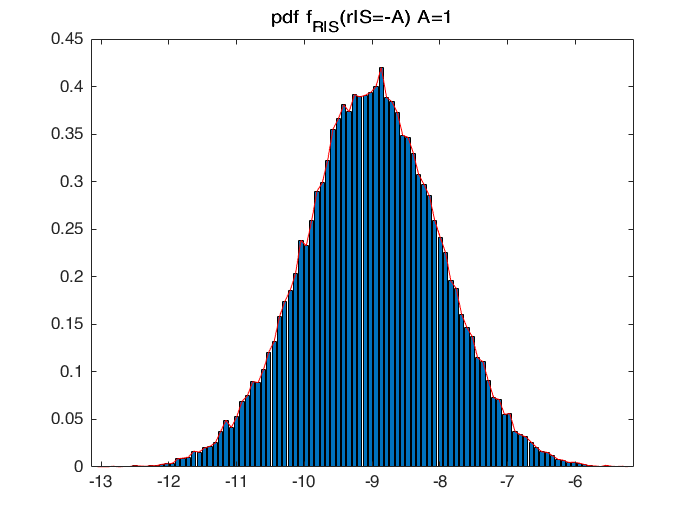



figure
bar(xval2,yval2);
hold on;
plot(xval2,yval2,'r'); 
title("pdf f_{R|S}(r|S=-A) A=1");

A=1;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
alpha = 1.8;
R = alpha*S + Noise;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

disp("For A=1");

For A=1


ER_SMA

ER_SMA = -9.0015

ER_SA

ER_SA = 9.0039

E_R

E_R = 0.0012

A=3;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
alpha = 1.8;
R = alpha*S + Noise;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

disp("For A=3");

For A=3


ER_SMA

ER_SMA = -9.0015

ER_SA

ER_SA = 9.0039

E_R

E_R = 0.1021


A=5;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
alpha = 1.8;
R = alpha*S + Noise;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

disp("For A=5");

For A=5


ER_SMA

ER_SMA = -9.0015

ER_SA

ER_SA = 9.0039

E_R

E_R = 0.1830

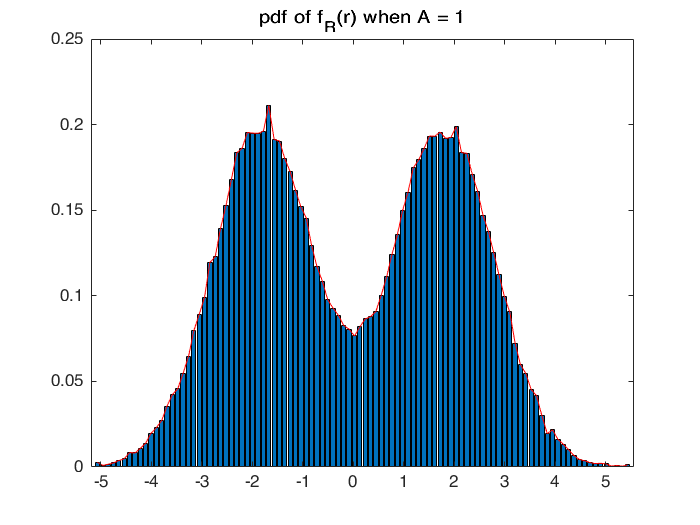



A=1;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
alpha = 1.8;
R = alpha*S + Noise;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

figure
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A = 1")

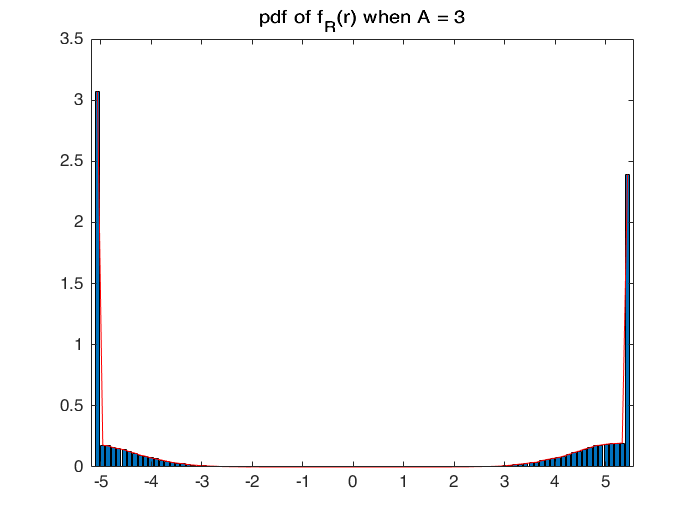



A=3;
%generating a sequence of pulses
S = zeros(1,L);
for i = 1:L
    if D(i) == 0 
        S(i) = -1*A;
    else
        S(i) = A; 
    end
end
alpha = 1.8;
R = alpha*S + Noise;

% E[R|S=A]
ER_SA = 0;
for i = 1:bin
 ER_SA = ER_SA + (xval1(i)*yval1(i)*W_1);
end

%E[R|S=-A]
ER_SMA = 0;
for i = 1:bin
 ER_SMA = ER_SMA + (xval2(i)*yval2(i)*widthS_A);
end

%E[R]
[yval,xval] = hist(R,bins);
yval = yval/(L*W);
E_R = 0;
for i = 1:bin
 E_R = E_R + (xval(i)*yval(i)*W);
end

figure
bar(xval,yval);
hold on;
plot(xval,yval,'r');
title("pdf of f_R(r) when A = 3")